# Lecture 13  Phase Retrieval

## 1. Phase retrieval problem introduction

### 1.1 Fourier domain imaging

In coherent lens-less optical imaging, the far-field propagation captures the Fourier domain of the object. The criterion for far-field propagation (Fraunhofer diffraction) as opposed to the near-field propagation (Fresnel diffraction) is characterized by the Fresnel number


$$\mathcal{f}=\frac{D^2 }{\lambda z}$$


When $\mathcal{f}\ll 11$, the free-space propagation can be considered as far-field, which gives the Fourier transform of the object. $\mathcal{f}\ll 1$can either imply 1) long propagation distance, z; or 2) short wavelength $\lambda$ (as in the example of X-ray or electron beam diffraction).

Another location to observe the far-field of an object is the back focal plane of an ideal lens. Each spatial frequency component $\left(k_x ,k_y \right)$ of the object can be considerd as a plane wave traveling along the direction $\left(\theta_x ,\theta_y \right)$, where $k_x =2\pi \sin \theta_x \;/\lambda$ and $k_y =2\pi \sin \theta_{y\;} /\lambda$. Because each plane wave focuses to a point $\left(x,y\right)$ on the back focal plane of an ideal infinitely-large lens, the back focal plane represents the Fourier transform of the object as a function of the spatial frequency components $k_x =\frac{2\pi x}{f\lambda }$, $k_y =\frac{2\pi y}{f\lambda }$.

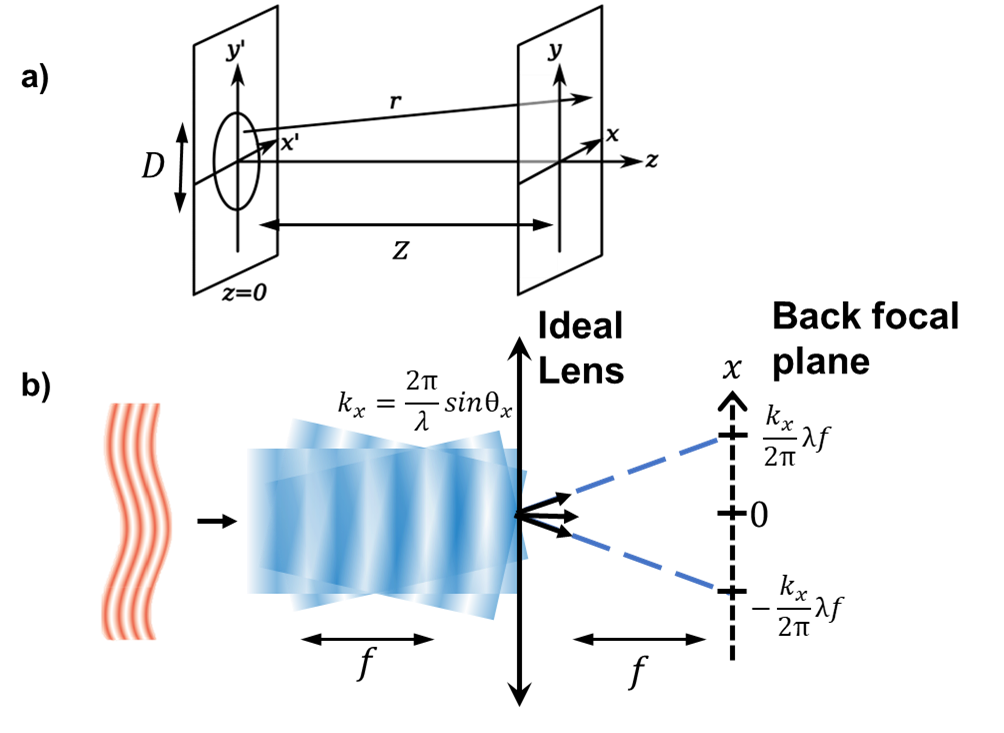

**ILL. 1.1*** Examples of Fourier transform pairs in coherent imaging: a) Far-field scalar wave propagation, and b) Front and back focal plane of an infinite-aperture ideal lens.*

### **1.2 Phase retrieval problem setup**

A normal CCD or CMOS panel detector can only measure the intensity distribution in the Fourier domain and/or object domain without the phase information. Phase retrieval is the problem to reconstruct the object (complex amplitude and phase) from intensity-only measurements in the Fourier and object domain. 

Example 1.1 shows the scenerio of a complex object $\tilde{g}$ with known amplitude $f$ and is uniform within a region-o-interest (ROI). The amplitude $F$ (known) and phase $\phi$ (unknown) of its Fourier domain $\tilde{G} =\textrm{FT}\left\lbrace \tilde{g} \right\rbrace$are simulated using discrete Fourier transform (DFT). The phase retrieval problem constructs $\theta$ and $\phi$ from the known amplitude measurements $F$ and $f$.

***Example 1.1 ***

Phase retrieval problem setup

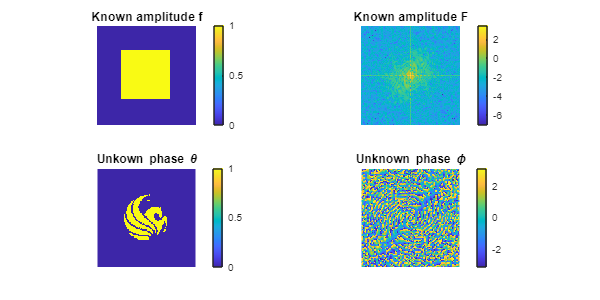

% Phase retrieval problem setup
load('UCF_logo.mat','f','ROI'); % phase pattern in 'f'
f_obj=ones(size(f)).*ROI.*exp(1i*f);
F_FFT=opt_fft2(f_obj);

% amplitude measurement
f=abs(f_obj);
F=abs(F_FFT);
save('PR_measurement.mat', 'F','f','ROI');

figure;
subplot(2,2,1);
imagesc(f);
axis image; axis off; axis tight;
colorbar; title('Known amplitude f');
subplot(2,2,2);
imagesc(log(F));
axis image; axis off; axis tight;
colorbar; title('Known amplitude F');
subplot(2,2,3);
imagesc(angle(f_obj));
axis image; axis off; axis tight;
colorbar; title('Unkown phase \theta');
subplot(2,2,4);
imagesc(angle(F_FFT));
axis image; axis off; axis tight;
colorbar; title('Unknown phase \phi');
set(gcf,'Position', [100 100 600 300])


$$\tilde{\mathit{\mathbf{g}}} =\mathbf{f}\;\exp \left(i\theta \right)\overset{\textrm{FT}}{\underset{\textrm{IFT}}{\iff}} \tilde{\mathit{\mathbf{G}}} =\mathbf{F}\;\exp \left(i\phi \right)$$
 

*Notes:*

- `opt_fft2`* performs optical Fourier transform (dc component is centered). Source code is attached in the **Appendix**.*

### 1.3 Properties of DFT operator

#### 1.3.1 Construction of the discrete Fourier transform operator (matrix)

The discrete Fourier transform is a linear operator that can be expressed in matrix form ${\mathbf{A}}_{\textrm{DFT}}$, assuming the object and Fourier domain are both vectorized. For 1D Fourier transforms, MATLAB's built-in function `dftmtx() `constructs the DFT matrix assuming zero frequency is located at the first element of the array. A 2D discrete Fourier transform matrix can be constructed as the Kronecker product between two 1D DFT matrices along the horizontal and vertical directions, respecetively.

#### 1.3.2 Properties of n-Dimensional DFT matrix

- ${\mathbf{A}}_{\textrm{DFT}}^T ={\mathit{\mathbf{A}}}_{\textrm{DFT}}$ (symmetric)

- ${\mathbf{A}}_{\textrm{DFT}}^{\dagger} ={\mathbf{A}}_{\textrm{DFT}}^{-1}$ (unitary)


$$\longrightarrow {\mathbf{A}}_{\textrm{DFT}}^* ={\mathbf{A}}_{\textrm{DFT}}^{\dagger} {=\mathbf{A}}_{\textrm{DFT}}^{-1}$$


The properties of the DFT matrix are useful in deriving the phase retrieval algorithms and performing error and convergence analysis.

***Example 1.2  ***

DFT matrix construction and its properties

% Construction of 2D discrete Fourier transform using kroneck product
% of 1D DFT matrices.
[Ny,Nx]=size(f);
Ay=fftshift(fftshift(dftmtx(Ny),2),1)/sqrt(Ny);
Ax=fftshift(fftshift(dftmtx(Nx),2),1)/sqrt(Nx);
A_DFT=kron(Ax,Ay);

% Fourier domain measurement simulated with DFT matrix
F_DFT=reshape(A_DFT*f_obj(:),Ny,Nx);

The DFT matrix is unitary and symmetric, and can be verified as following:

- The DFT matrix is symmetric. Note here that (`.'`) calculates the transpose

              `isequaln(A_DFT.',A_DFT) % = true`

          2. The DFT matrix is unitary. Its conjugate transpose (`'`) is also it inverse.

               `isequaln(A_DFT'*A_DFT,eye(Ny,Nx) % = true`

If we have the complete amplitude and phase in Fourier domain, we can analytically reconstruct the object domain with an inverse Fourier transform. Here the inverse Fourier transform is performed using 1) built-in `ifft2`, and 2) the complex conjugate of the DFT matrix inverse.

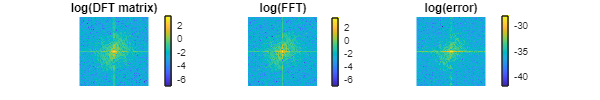

% Verify and illustrate the properties of DFT matrix 
% and its inverse with FFT results
f_hat=opt_ifft2(F_FFT);
f_hat_DFT=reshape(A_DFT'*F_FFT(:),Ny,Nx);

figure;
subplot(1,3,1)
imagesc(log(abs(F_DFT)));
axis image; axis off; axis tight;
colorbar; title('log(DFT matrix)');
subplot(1,3,2);
imagesc(log(abs(F_FFT)));
axis image; axis off; axis tight;
colorbar; title('log(FFT)');
subplot(1,3,3)
imagesc(log(abs(F_DFT-F_FFT)));
axis image; axis off; axis tight;
colorbar; title('log(error)');
set(gcf,'Position', [100 100 600 100])

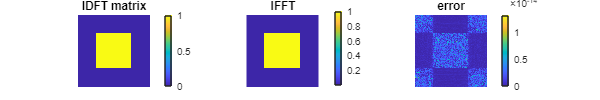

figure;
subplot(1,3,1)
imagesc(abs(f_hat));
axis image; axis off; axis tight;
colorbar; title('IDFT matrix');
subplot(1,3,2);
imagesc(abs(f_hat_DFT));
axis image; axis off; axis tight;
colorbar; title('IFFT');
subplot(1,3,3)
imagesc(abs(f_hat_DFT-f_hat));
axis image; axis off; axis tight;
colorbar; title('error');
set(gcf,'Position', [100 100 600 100])

*Notes:*

- `opt_ifft2`* performs inverse optical Fourier transform (dc component is centered). Source code is attached in the **Appendix**.*

## 2. Phase retrieval algorithms

### 2.1 Gradient-based phase retrieval

The most straight-forward way of solving the phase retrieval problem comes from the perspective of nonlinear optimization using gradient-descent iterations. This is also known as the "error reduction" algorithm in the literature *Fienup , Appl. Opt. 1982.*

An optimization problem defines an objective $l\left(\theta \right)$ as a function of $\theta$. The gradient-descent process starts with an initial trial solution $\theta_0$. In iteration $k$, the algorithm calculates the gradient $\frac{\partial l}{\partial \theta }|_{\theta_k }$ and updates the trial solution along the gradient direction by a step size $\tau$ to minimize $l$.


$$\theta_{k+1} =\theta_k -\tau \frac{\partial l\left(\theta \right)}{\partial \theta }|_{\theta_k }$$


The objective function of the phase retrieval problem can be defines as the L2 norm (error) of the amplitude in either Fourier or object domain. Most commonly, the objective is defined in the Fourier domain, by comparing the amplitudes between measured diffraction field $\mathbf{F}$ and the one from trial solution $\mathbf{G}=\tilde{\left|\mathbf{G}\right|}$.


$$l\left(\theta \right)={\left(\tilde{\left|\mathbf{G}\right|} -\mathbf{F}\right)}^2 ={\left(\left|{\mathbf{A}}_{\textrm{DFT}} \left(\mathbf{f}\odot \exp \left(i\theta \right)\right)\right|-\mathbf{F}\right)}^2$$


Because the complex modulus operator $\tilde{\left|z\right|}$ is not differentiable around the vicinity of $\tilde{z}$, we need to treat $\tilde{\mathbf{G}}$ and ${\tilde{\mathbf{G}} }^*$ as independent variable and aggregate individual gradients with respect to $\theta$ (this is known as Wirtinger derivative, an equivalent "chain rule" for complex-variable function). 


$$\frac{\partial l}{\partial \theta }=2\underset{\underset{\textrm{Jacobian}\;\textrm{matrix}}{\downarrow} }{\frac{\partial \sqrt{\tilde{\mathbf{G}} {\tilde{\mathbf{G}} }^* }}{\partial \theta }} \cdot \left(\tilde{\left|\mathbf{G}\right|} -\mathbf{F}\right)=\left\lbrack \frac{\partial {\tilde{\mathbf{G}} }^* }{\partial \theta }\textrm{diag}\left(\tilde{\mathbf{G}} \right)+\frac{\partial \tilde{\mathbf{G}} }{\partial \theta }\textrm{diag}\left({\tilde{\mathbf{G}} }^* \right)\right\rbrack \cdot \left(\frac{\tilde{\left|\mathbf{G}\right|} -\mathbf{F}}{\left|\tilde{\mathbf{G}} \right|}\right)$$


Using $\tilde{\mathbf{G}} ={\mathbf{A}}_{\textrm{DFT}} \left(\mathbf{f}\odot \exp \left(i\theta \right)\right)$, we have


$$\frac{\partial {\tilde{\mathbf{G}} }^{\ast } }{\partial \theta }=-i\;\textrm{diag}\left(\mathbf{f}\odot \exp \left(-i\theta \right)\right){\mathbf{A}}_{\textrm{DFT}}^{\dagger}$$



$$\frac{\partial \tilde{\mathbf{G}} }{\partial \theta }=i\;\textrm{diag}\left(\mathbf{f}\odot \exp \left(i\theta \right)\right){\mathbf{A}}_{\textrm{DFT}}^T$$


Substituting these two terms in the gradient, and applying the properties of discrete Fourier transform matrix ${\mathbf{A}}_{\textrm{DFT}}^* ={\mathbf{A}}_{\textrm{DFT}}^{\dagger} ={\mathbf{A}}_{\textrm{DFT}}^{-1}$, we can formulate the gradient as an inverse Fourier transform


$$\frac{\partial l}{\partial \theta }=i\left\lbrace \textrm{diag}\left(\mathbf{f}\odot \exp \left(-i\theta \right)\right){\mathbf{A}}_{\textrm{DFT}}^{\dagger} \textrm{diag}\left(\tilde{\mathbf{G}} \right)\left(\tilde{\frac{\left|\mathbf{G}\right|-\mathbf{F}}{\left|\tilde{\mathbf{G}} \right|}} \right)-c\ldotp c\right\rbrace$$



$$=2\textrm{Im}\left\lbrace {\tilde{\mathit{\mathbf{g}}} }^* \odot \left\lbrack {\mathbf{A}}_{\textrm{DFT}}^{\dagger} \left(\tilde{\mathbf{G}} -\mathbf{F}\tilde{\frac{\mathbf{G}}{\left|\tilde{\mathbf{G}} \right|}} \right)\right\rbrack \right\rbrace$$



$$=2\textrm{Im}\left\lbrace {\tilde{\mathit{\mathbf{g}}} }^* \odot \left\lbrack {\mathbf{A}}_{\textrm{DFT}}^{\dagger} \left(\tilde{\mathbf{G}} \mathbf{F}\;\exp \left(i\phi \right)\right)\right\rbrack \right\rbrace$$


Here '$\odot$' denotes element-wise product. Note in the last step, ${\mathbf{A}}_{\textrm{DFT}}^{\dagger} \tilde{\mathbf{G}} =\tilde{\mathit{\mathbf{g}}}$, and ${\tilde{\mathit{\mathbf{g}}} }^* \odot$$\tilde{\mathit{\mathbf{g}}}$ is a real vector that does not contain any imaginary components.

A reference step size, $\tau$, can be derived from the local gradient at $k$-th iteration using Newton's method. 


$$l\left(\theta \right)=l\left(\theta_k \right)+\frac{\partial l}{\partial \theta }|_{\theta_k } \;\left(\theta -\theta_k \right)$$


Zero of the linear expansion of the objective occurs at


$$\left(\theta -\theta_k \right)=\frac{\partial l}{\partial \theta }|_{\theta_k } \cdot \frac{l\left(\theta_k \right)}{{\left|\frac{\partial l}{\partial \theta }|_{\theta_k } \right|}^2 }\equiv \frac{\partial l}{\partial \theta }|_{\theta_k } \cdot \tau$$


Here $\tau =\frac{l\left(\theta_k \right)}{{\left|\frac{\partial l}{\partial \theta }|_{\theta_k } \right|}^2 }$ is the reference point for determining the orfer of magnitude of the step size. Therefore, the gradient-based phase retrieval updates $\theta$ in each iteration as follows:


$$\theta_{k+1} =\theta_k +\tau \textrm{Im}\left\lbrace {\tilde{\mathbf{g}} }^* \odot \textrm{IFT}\;\left\lbrace \mathbf{F}\;\exp \left(i\phi \right)\right\rbrace \right\rbrace$$


***Example 2.1 ***

Phase retrieval with gradient-descent optimization

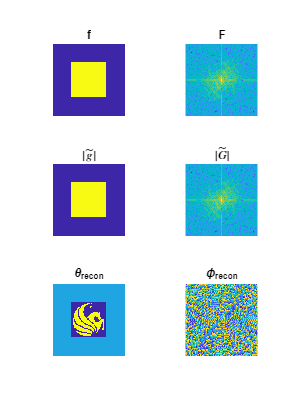

% Fourier-domain objective 
clear
load('PR_measurement.mat','F','f','ROI');

N_iter=6000;
tau_factor=0.5;
epsilon=1e-8; % safe-guard division by 0

error_F=zeros(N_iter,1);
theta_hat=zeros(size(f));
g_tilde=f.*exp(1i*theta_hat);

% Gradient descent iteration
for ii=1:N_iter
    G_tilde=opt_fft2(g_tilde);
    G=abs(G_tilde);
    error_F(ii)=NMSE(G,F);
    phi_hat=angle(G_tilde);
    grad_theta=-2*imag(conj(g_tilde).*opt_ifft2(F.*exp(1i*phi_hat))); % gradient of Fourier-domain objective
    tau_theta=tau_factor*sum((G(:)-F(:)).^2)/sum(abs(grad_theta(:)).^2+epsilon); % Newtonian step size
    theta_hat=theta_hat-tau_theta*grad_theta; % phase update
    g_tilde=f.*exp(1i*theta_hat);
end

g=abs(g_tilde);
figure;
subplot(3,2,1);
imagesc(f);
axis image; axis image; axis off; axis tight;
title('f');
subplot(3,2,2);
imagesc(log(F));
axis image; axis image; axis off; axis tight;
title('F');
subplot(3,2,3);
imagesc(g.*ROI);
axis image; axis off; axis tight;
title('$$|\tilde{g}|$$','Interpreter','Latex');
subplot(3,2,4);
imagesc(log(G));
axis image; axis off; axis tight;
title('$$|\tilde{G}|$$','Interpreter','Latex');
subplot(3,2,5);
imagesc(theta_hat.*ROI);
axis image; axis off; axis tight;
title('\theta_{recon}');
subplot(3,2,6);
imagesc(phi_hat);
axis image; axis off; axis tight;
title('\phi_{recon}');
set(gcf,'Position', [100 100 300 400])

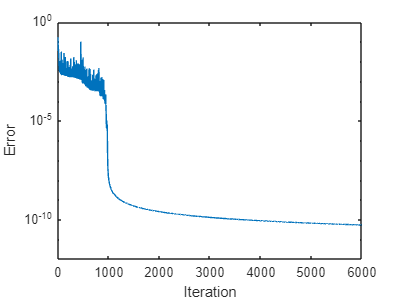

figure;
semilogy(error_F);
set(gcf,'Position', [100 100 400 300])
xlabel("Iteration")
ylabel("Error")

*Notes:*

- `NMSE`* calculates the normalized mean square error. Source code is attached in the **Appendix*

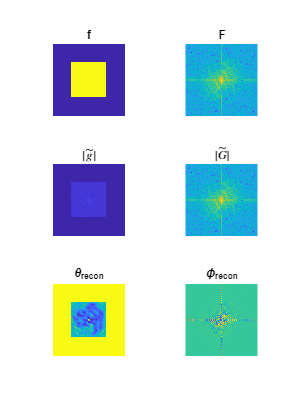

% Object-domain objective
N_iter=6000;
tau_factor=0.005;
epsilon=1e-8; % safe-guard division by 0

error_f=zeros(N_iter,1);
phi_hat=zeros(size(f));
G_tilde=F.*exp(1i*phi_hat);

% Gradient descent iteration
for ii=1:N_iter
    g_tilde=opt_ifft2(G_tilde);
    g=abs(g_tilde);
    error_f(ii)=NMSE(g,f);
    theta_hat=angle(g_tilde);
    grad_phi=-2*imag(conj(G_tilde).*opt_fft2(f.*exp(1i*theta_hat))); % gradient of object-domain objective
    tau_phi=tau_factor*sum((g(:)-f(:)).^2)/sum(abs(grad_phi(:)).^2+epsilon); % Newtonian step size
    phi_hat=phi_hat-tau_phi*grad_phi; % phase update
    G_tilde=F.*exp(1i*phi_hat);
end

figure;
subplot(3,2,1);
imagesc(f);
axis image; axis image; axis off; axis tight;
title('f');
subplot(3,2,2);
imagesc(log(F));
axis image; axis image; axis off; axis tight;
title('F');
subplot(3,2,3);
imagesc(g.*ROI);
axis image; axis image; axis off; axis tight;
title('$$|\tilde{g}|$$','Interpreter','Latex');
subplot(3,2,4);
imagesc(log(G));
axis image; axis image; axis off; axis tight;
title('$$|\tilde{G}|$$','Interpreter','Latex');
subplot(3,2,5);
imagesc(theta_hat.*ROI);
axis image; axis image; axis off; axis tight;
title('\theta_{recon}');
subplot(3,2,6);
imagesc(phi_hat);
axis image; axis image; axis off; axis tight;
title('\phi_{recon}');
set(gcf,'Position', [100 100 300 400])

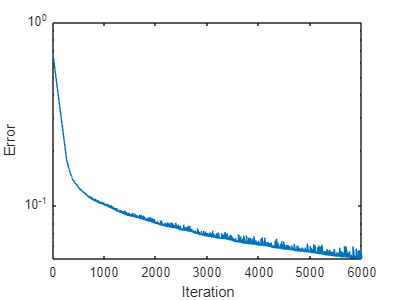

figure;
semilogy(error_f);
set(gcf,'Position', [100 100 400 300])
xlabel("Iteration")
ylabel("Error")

### 2.2 Stationary point and Gerchberg-Saxton (GS) algorithm

We can also try to move the solution directly to the stationary point $\frac{\partial l}{\partial \theta }=0$ in each iteration. 


$$\frac{\partial l}{\partial \theta }=-2\textrm{Im}\left\lbrace \mathbf{f}\odot \exp \left(-i\theta \right)\odot \textrm{IFT}\left\lbrace \mathbf{F}\tilde{\mathbf{G}} \left(\theta \right)/\left|\tilde{\mathbf{G}} \left(\theta \right)\right|\right\rbrace \right\rbrace$$



$$=-2\textrm{Im}\left\lbrace \mathbf{f}\odot \exp \left(-i\theta \right)\odot \textrm{IFT}\left\lbrace \mathbf{F}\;\exp \left(i\phi \right)\right\rbrace \right\rbrace$$


Since $\frac{\partial l}{\partial \theta }=0$ has no analytical solution because $\phi$ is also a function of $\theta$ (due to $\tilde{\mathbf{G}} \left(\theta \right)$), we can only approximate the stationary point with,

$\theta =\textrm{angle}\left(\textrm{IFT}\left\lbrace \mathbf{F}\;\exp \left(i\phi \right)\right\rbrace \right)$.

This approximation is "accurate" when $\theta \;$ is small (i.e., $\exp \left(-i\theta \;\right)\approx 1-i\theta \;$). The approximated stationary-point iteration plus the steps of calculating $\tilde{\mathbf{G}}$ constitutes the Gerchberg-Saxton (GS) algorithm:

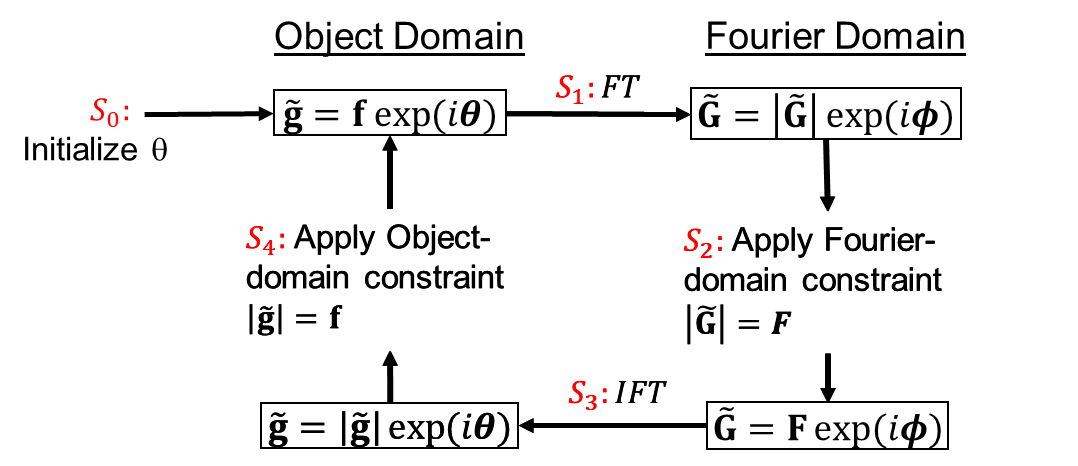

**ILL. 2.1 ***GS flow-chart *

***Example 2.2 ***

Phase retrieval with GS algorithm

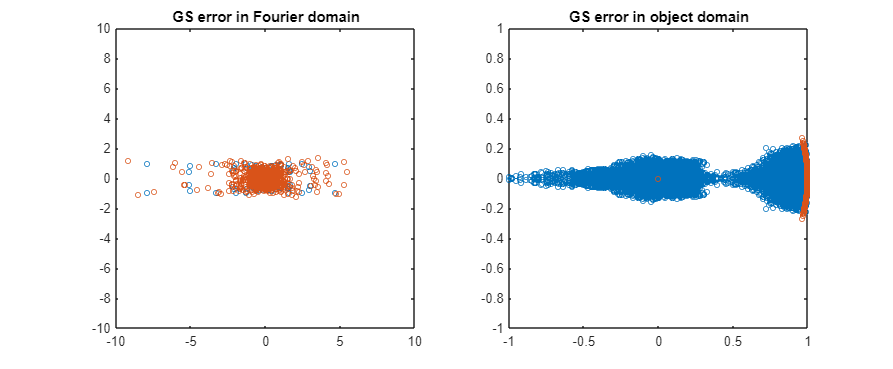

% GS algorithm setup
clear; close all;clc;
load('PR_measurement.mat','F','f','ROI');
N_iter=3000;
error_F=zeros(N_iter,1);
error_f=zeros(N_iter,1);

theta_hat=zeros(size(f));
g_tilde=f.*exp(1i*theta_hat);
% save intermediate results for plotting
G_tilde_save=zeros(numel(F),N_iter);
G_true_save=zeros(numel(F),N_iter);
g_tilde_save=zeros(numel(f),N_iter);
g_true_save=zeros(numel(f),N_iter);

% GS algorithm
for ii=1:N_iter
    G_tilde=opt_fft2(g_tilde); % S1

    G_tilde_save(:,ii)=G_tilde(:); % plot GS error - G_tilde

    G=abs(G_tilde);
    phi_hat=angle(G_tilde);
    error_F(ii)=NMSE(G,F); % plot GS error - Fourier-domain objective
    G_tilde=F.*exp(1i*phi_hat); % S2
    g_tilde=opt_ifft2(G_tilde); % S3

    g_tilde_save(:,ii)=g_tilde(:); % plot GS error - g_tilde

    g=abs(g_tilde);
    theta_hat=angle(g_tilde);
    error_f(ii)=NMSE(g,f); % plot GS error - object-domain objective
    g_tilde=f.*exp(1i*theta_hat); % S4

    g_true_save(:,ii)=g_tilde(:); % plot GS error - g_true
    G_true_save(:,ii)=F(:).*exp(1i*phi_hat(:)); % plot GS error - G_true
    
end

figure;
subplot(1,2,1);
plot(G_tilde_save(:,1),"o",'MarkerSize',4); hold on;
subplot(1,2,2);
plot(g_tilde_save(:,1),"o",'MarkerSize',4); hold on;
subplot(1,2,2);
plot(g_true_save(:,1),"o",'MarkerSize',4); hold off;
xlim([-1,1]);ylim([-1,1]);
title('GS error in object domain');
subplot(1,2,1);
plot(G_true_save(:,1),"o",'MarkerSize',4);hold off;
xlim([-10,10]);ylim([-10,10]);
title('GS error in Fourier domain');
set(gcf,'Position',[341   507   899   371]);

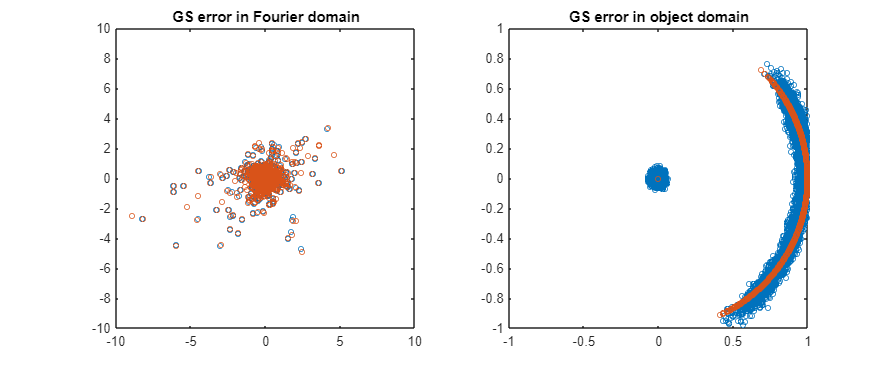

figure;
subplot(1,2,1);
plot(G_tilde_save(:,floor(N_iter/8)),"o",'MarkerSize',4); hold on;
subplot(1,2,2);
plot(g_tilde_save(:,floor(N_iter/8)),"o",'MarkerSize',4); hold on;
subplot(1,2,2);
plot(g_true_save(:,floor(N_iter/8)),"o",'MarkerSize',4); hold off;
xlim([-1,1]);ylim([-1,1]);
title('GS error in object domain');
subplot(1,2,1);
plot(G_true_save(:,floor(N_iter/8)),"o",'MarkerSize',4);hold off;
xlim([-10,10]);ylim([-10,10]);
title('GS error in Fourier domain');
set(gcf,'Position',[341   507   899   371]);

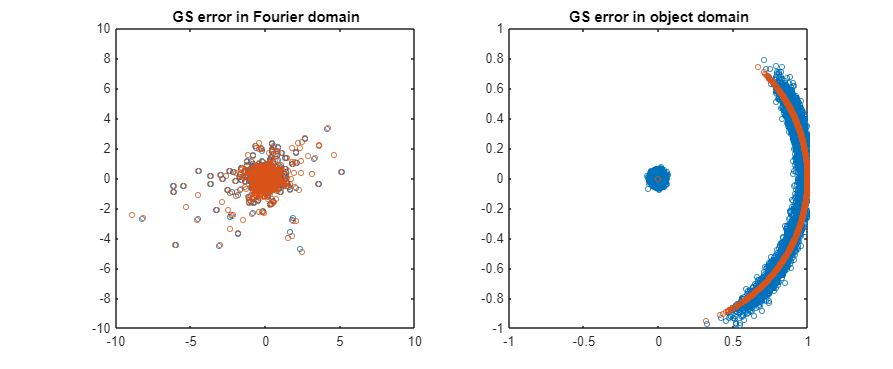

figure;
subplot(1,2,1);
plot(G_tilde_save(:,floor(N_iter/4)),"o",'MarkerSize',4); hold on;
subplot(1,2,2);
plot(g_tilde_save(:,floor(N_iter/4)),"o",'MarkerSize',4); hold on;
subplot(1,2,2);
plot(g_true_save(:,floor(N_iter/4)),"o",'MarkerSize',4); hold off;
xlim([-1,1]);ylim([-1,1]);
title('GS error in object domain');
subplot(1,2,1);
plot(G_true_save(:,floor(N_iter/4)),"o",'MarkerSize',4);hold off;
xlim([-10,10]);ylim([-10,10]);
title('GS error in Fourier domain');
set(gcf,'Position',[341   507   899   371]);

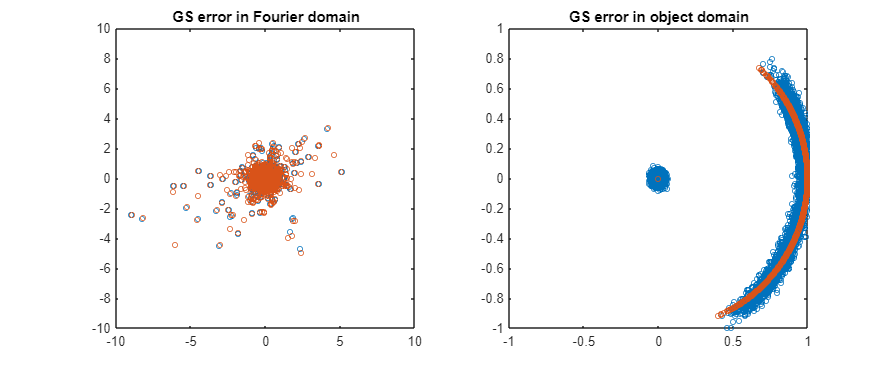

figure;
subplot(1,2,1);
plot(G_tilde_save(:,floor(N_iter/2)),"o",'MarkerSize',4); hold on;
subplot(1,2,2);
plot(g_tilde_save(:,floor(N_iter/2)),"o",'MarkerSize',4); hold on;
subplot(1,2,2);
plot(g_true_save(:,floor(N_iter/2)),"o",'MarkerSize',4); hold off;
xlim([-1,1]);ylim([-1,1]);
title('GS error in object domain');
subplot(1,2,1);
plot(G_true_save(:,floor(N_iter/2)),"o",'MarkerSize',4);hold off;
xlim([-10,10]);ylim([-10,10]);
title('GS error in Fourier domain');
set(gcf,'Position',[341   507   899   371]);

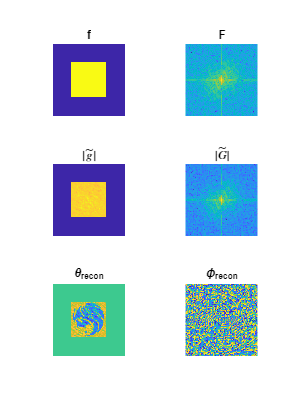

figure;
subplot(3,2,1);
imagesc(f);
axis image; axis image; axis off; axis tight;
title('f');
subplot(3,2,2);
imagesc(log(F));
axis image; axis image; axis off; axis tight;
title('F');
subplot(3,2,3);
imagesc(g.*ROI);
axis image; axis off; axis tight;
title('$$|\tilde{g}|$$','Interpreter','Latex');
subplot(3,2,4);
imagesc(log(G));
axis image; axis off; axis tight;
title('$$|\tilde{G}|$$','Interpreter','Latex');
subplot(3,2,5);
imagesc(theta_hat.*ROI);
axis image; axis off; axis tight;
title('\theta_{recon}');
subplot(3,2,6);
imagesc(phi_hat);
axis image; axis off; axis tight;
title('\phi_{recon}');
set(gcf,'Position', [100 100 300 400])

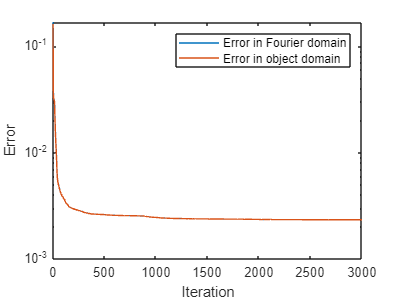

figure;
semilogy(error_F); hold on;
semilogy(error_f); hold off; % add in the x y label
legend('Error in Fourier domain','Error in object domain');
set(gcf,'Position', [100 100 400 300])
xlabel("Iteration")
ylabel("Error")

Although GS algorithm does not strictly follow the gradient direction, the objective function always improves (or stays the same) during each GS iteration. To illustrate this, we examine the objective function 


$$l={\left|\left|\tilde{\mathbf{G}} \right|-\mathbf{F}\right|}^2 =\sum_u {\left(\left|\tilde{{\mathbf{G}}_u } \right|-F_u \right)}^2 =\sum_u {\left|\tilde{{\mathbf{G}}_u } \right|}^2 +\sum_u F_u^2 -2\sum_u F_u \left|\tilde{{\mathbf{G}}_u } \right|$$


Using Parseval's theorem (unitary transformation),


$$\sum_u {\left|\tilde{{\mathbf{G}}_u } \right|}^2 =\sum_u F_u^2 =\sum_u f_u^2 =I$$


where $I$ represents the constant, total intensity. Therefore,


$$l=2I-2\sum_u F_u \left|\tilde{{\mathbf{G}}_u } \right|$$


where $C=\sum_u F_u \left|\tilde{{\mathbf{G}}_u } \right|$ can be considered as the amplitude "overlap integral".

After step S1, we obtain $\tilde{\mathbf{G}} ={\mathbf{A}}_{\textrm{DFT}} \left\lbrack \mathbf{f}\;\exp \left(i\theta \right)\right\rbrack$. ILL. 2.2 illustrates the errors and change in the vector $\tilde{\mathbf{G}}$ during step S2: Apply Fourier domain constraints.

- Moving the vector $\left|\tilde{\mathbf{G}} \right|$ along the amplitude circle to the point of tangency $\mathbf{F}$ maximizes the amplitude overlap integral $C$, and thus minimizes $l$.

- Retaining the phase of individual ${\tilde{G} }_u$ minimizes the modulus of $\left|\Delta {\tilde{G} }_u \right|$, lowering the upper bound of discrepancy in object domain, $\left|{\tilde{\mathbf{g}} }^{\prime } -\tilde{\mathbf{g}} \right|$, before and after Fourier domain modification. The upper bound of $\left|{\tilde{\mathbf{g}} }^{\prime } -\tilde{\mathbf{g}} \right|$ is given by

   
$$\left|{\tilde{\mathbf{g}} }^{\prime } -\tilde{\mathbf{g}} \right|\le \left|\tilde{\mathbf{g}} \right|+\left|{\tilde{\mathbf{g}} }^{\prime } \right|=\left|{\mathbf{A}}_{\textrm{DFT}}^{\dagger} \tilde{\mathbf{G}} \right|+\left|{\mathbf{A}}_{\textrm{DFT}}^{\dagger} \left\lbrack \tilde{\mathbf{G}} +\Delta \tilde{\mathbf{G}} \right\rbrack \right|\le 2\left|{\mathbf{A}}_{\textrm{DFT}}^{\dagger} \tilde{\mathbf{G}} \right|+\left|{\mathbf{A}}_{\textrm{DFT}}^{\dagger} \tilde{\Delta \mathit{\mathbf{G}}} \right|\le 2\left|{\mathbf{A}}_{\textrm{DFT}}^{\dagger} \tilde{\mathbf{G}} \right|+\left|{\mathbf{A}}_{\textrm{DFT}}^{\dagger} \left|\Delta \tilde{\mathbf{G}} \right|\right|$$


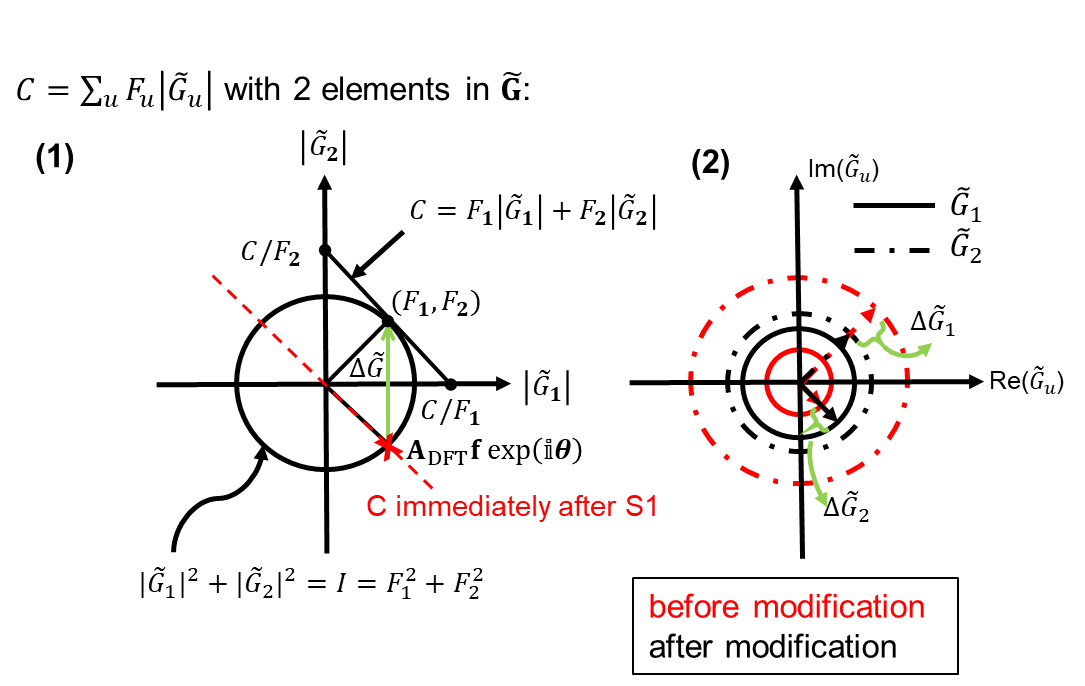

**ILL. 2.2 ***GS iteration step and error if *$\tilde{\mathbf{G}}$* only has two elements. (1) and (2) depict their amplitude and phase, respectively.*

## **3. GS algorithm with single-intensity measurement**

The object-domain intensity is not always measurable in practice. With a single intensity measurment in Fourier domain, the solution comtains ambiguity. Nevertheless, if we have partial knowledge about the object domain amplitude distribution, we can still use GS algorithm to find a solution that satisfies partial constraints in object domain by modifying step S4.

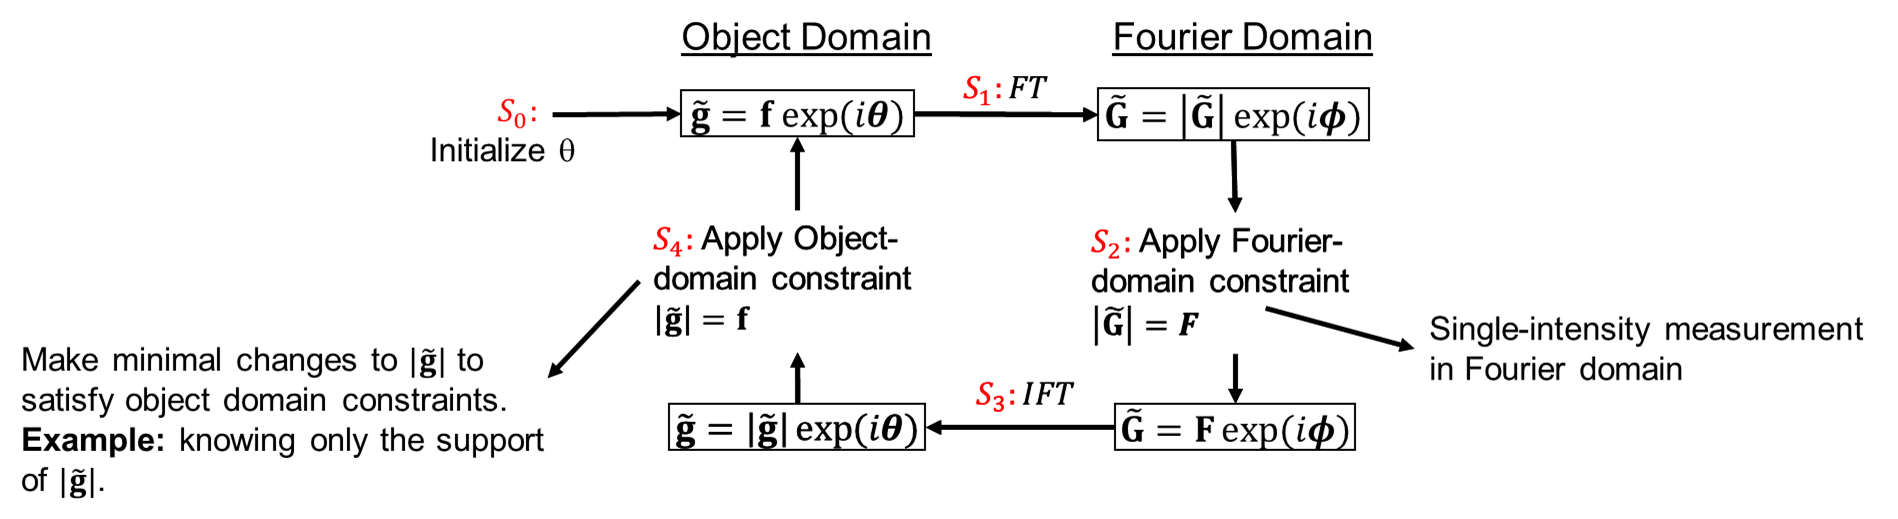

**ILL. 3.1 ***GS with single-intensity measurement*

***Example 3.1 Phase retrieval with partial constraints in GS algorithm***

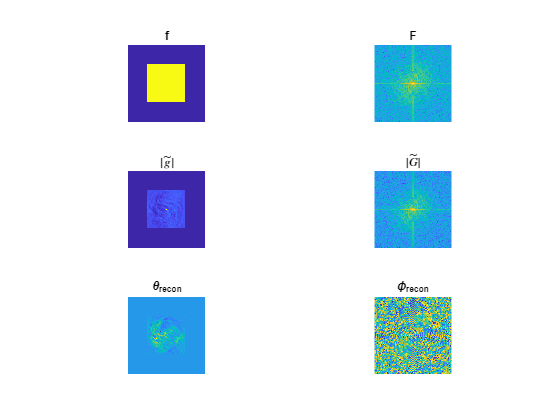

% GS algorithm setup
load('PR_measurement.mat','F','f','ROI');
N_iter=3000;
beta=0.2; % scaling factor for pixels outside ROI
error_F=zeros(N_iter,1);
error_f=zeros(N_iter,1);
phi_hat=rand(size(F));

% GS algorithm with partial constraints
for ii=1:N_iter
    G_tilde=F.*exp(1i*phi_hat);
    g_tilde=opt_ifft2(G_tilde);
    g=abs(g_tilde);
    f_hat=g.*ROI;
    f_hat(not(ROI))=g(not(ROI))*beta;
    theta_hat=angle(g_tilde);
    g_tilde=f_hat.*exp(1i*theta_hat);
    G_tilde=opt_fft2(g_tilde);
    G=abs(G_tilde);
    phi_hat=angle(G_tilde);
    error_F(ii)=NMSE(G,F);
end

figure;
subplot(3,2,1);
imagesc(f);
axis image; axis image; axis off; axis tight;
title('f');
subplot(3,2,2);
imagesc(log(F));
axis image; axis image; axis off; axis tight;
title('F');
subplot(3,2,3);
imagesc(g.*ROI);
axis image; axis off; axis tight;
title('$$|\tilde{g}|$$','Interpreter','Latex');
subplot(3,2,4);
imagesc(log(G));
axis image; axis off; axis tight;
title('$$|\tilde{G}|$$','Interpreter','Latex');
subplot(3,2,5);
imagesc(theta_hat.*ROI);
axis image; axis off; axis tight;
title('\theta_{recon}');
subplot(3,2,6);
imagesc(phi_hat);
axis image; axis off; axis tight;
title('\phi_{recon}');

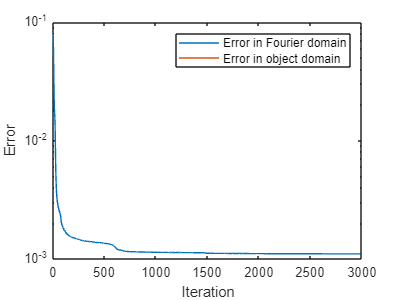

figure;
semilogy(error_F); hold on;
semilogy(error_f); hold off;
legend('Error in Fourier domain','Error in object domain');
set(gcf,'Position', [100 100 400 300])
xlabel("Iteration")
ylabel("Error")

## 4. Appendix: Helper functions

### opt_fft2

Optical Fourier transform

function [F] = opt_fft2(f)
%OPT_FFT Optical FFT as a unitary transformation
[Ny,Nx]=size(f);
F=fftshift(fft2(ifftshift(f)))/sqrt(Ny*Nx);
end

### opt_ifft2

Optical Inverse Fourier transform

function [f] = opt_ifft2(F)
%OPT_FFT Optical IFFT as a unitary transformation
[Ny,Nx]=size(F);
f=fftshift(ifft2(ifftshift(F)))*sqrt(Ny*Nx);
end

### NMSE

Normalized mean square error

function [NMSE] = NMSE(g,f)
%NMSE Calculates the normalized mean square error
NMSE=sum(abs(g(:)-f(:)).^2)/sum(abs(f(:)).^2);
end